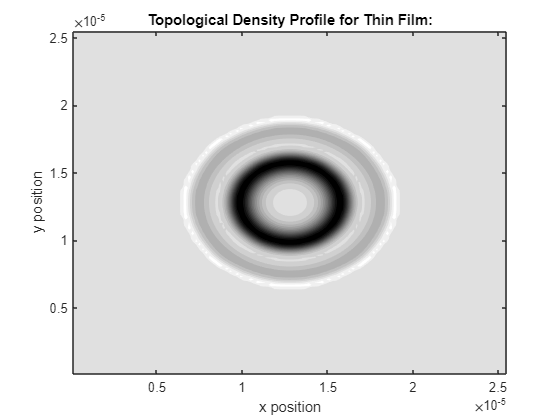

%
% Created on wed Jun 1 11:43:51 2022
%
% @author: BRasmussen
%
% Script to calculate topological density of given input magnetization
% layer for specific magnetization orientation.


% First need to load in data and split into components:

% Filename on current path:

Filename = "skyrmiondata.txt"; % change this depending on wanted input
data = importdata(Filename);

% If data has multiple layers, the following can be used to configure
% the desired truncation: 


datalayer = "Layer 4" ;  %Input string is used below 

% following code depends on size of file. Assuming that the data structure
% is a n x n grid with four layers:

% In this case n = 128 but can easily be changed

nn = 128;


if datalayer=="Layer 1"            %strings can be changed for num of layers
    layerdata = data(1:(nn^2),:);

elseif datalayer == "Layer 2"
    layerdata = data((nn^2 + 1):(2*nn^2),:);

elseif datalayer == "Layer 3"
    layerdata = data((2*nn^2+1):(3*nn^2),:);

elseif datalayer == "Layer 4"
    layerdata = data((3*nn^2+1):(4*nn^2),:);
end



%splits data into components for easier comprehension

X = layerdata(:,1); Y = layerdata(:,2); Z = layerdata(:,3);
Mx = layerdata(:,4); My = layerdata(:,5); Mz = layerdata(:,6);


% Using the topological density function at end of script we can now
% get our desired dataset. The output layer will be n x n corresponding to
% the n x n X-Y plane grid from the input data:

[TopDense, skyrnum] = topdensefunc(X,Y,Z,Mx,My,Mz);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Following code can be used to visualize the topological density data as
% well as local averages of the magnetization components in the X-Y plane
%
% plottable matrices for the above variables:

Mxplot = reshape(Mx,128,128); Myplot = reshape(My,128,128);
Mzplot = reshape(Mz,128,128); Xplot = reshape(X,128,128); 
Yplot = reshape(Y,128,128); Zplot = reshape(Z,128,128);


%% 
% In this section a local average of the magnetization components is
% found using a 2 dimensional convolution which is subsequently shrunk to
% the desired dimensions of the vector plot:

windowmatrix = ones(5,5)/5^2; % window size can be adjusted accordingly

convMx = conv2(Mxplot,windowmatrix,'same');
convMy = conv2(Myplot, windowmatrix, 'same');
convMz = conv2(Mzplot,windowmatrix,'same');

%Using the above we now want to shrink the matrix to the desired number of
%quiver arrows;

shrinkfactor = 4;  % must be factor of n

buffer = convMx(:,1:shrinkfactor:end) ;
Mx_reduced = buffer(1:shrinkfactor:end,:) ;

buffer = convMy(:,1:shrinkfactor:end) ;
My_reduced = buffer(1:shrinkfactor:end,:) ;

buffer = convMz(:,1:shrinkfactor:end) ;
Mz_reduced = buffer(1:shrinkfactor:end,:) ;

%now need plottable x and y vectors with the same dimension as the above
%reduced magnetization matrices:

X_reduced = X(1:shrinkfactor:end,:);
Y_reduced = Y(1:shrinkfactor:end,:);
Z_reduced = Z(1:shrinkfactor:end,:);

X_reducedplot = X_reduced(1:128/shrinkfactor);
Y_reducedplot = X_reducedplot;
Z_reducedplot = X_reducedplot;

%%


% In order to plot the figure using a contour plot the following code will
% create an image:
figure()
C = contourf(Xplot,Yplot,TopDense, 16, "LineColor", 'none'); % also just contour

% Colormap can be changed to whatever is needed:
%load('topdense2.mat')
colormap(gray)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")

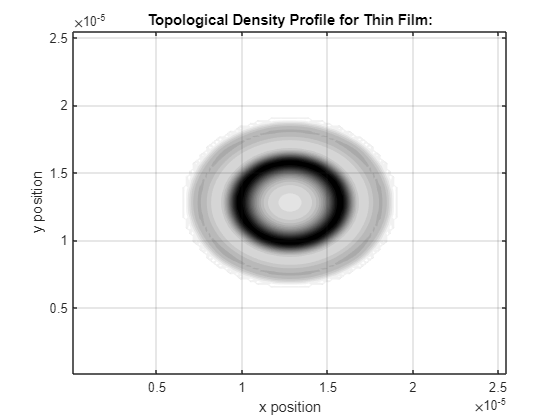


topdense2 = TopDense;

topdense2(topdense2==0) = NaN;




figure()
C = contourf(Xplot,Yplot,topdense2, 18, "LineColor", 'none'); % also just contour

% Colormap can be changed to whatever is needed:
%load('topdense2.mat')
colormap(gray)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")

% Just comment this out to get rid of arrows 

hold on
%q = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced,0.5);
%q.Color = '[0,0,0.3]';
hold off
grid on


















%max_contour = max(TopDense);
%max_ = max(max_contour)
%sub_matrix = ones(nn)*max_;
%TopDense_sub = imsubtract(TopDense, -sub_matrix);

%C = contour(Xplot,Yplot,TopDense_sub, 16, "LineColor", 'none');
%colormap(gray)







%{
saveas(gcf, 'contour.png')

I = imread('contour.png');
imshow(I);
background = imopen(I,strel('disk', 500));

imshow(background)

D = imsubtract(I,background);

imshow(D ...
    )

%}














% In order to plot the figure using a contour plot the following code will
% create an image:


%{
contourf(Xplot,Yplot,TopD, 5, "LineColor", 'none')
colormap(topdense2)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")
hold on
q3 = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced,0.3);
q3.Color = '[0.2,0,0.2]';
hold off
Xtick = linspace(0,2.55e-5,10);
grid on
%}



























% Just comment this out to get rid of arrows 

%hold on
%q = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced,0.5);
%q.Color = '[0,0,0.3]';
%hold off
%grid on

